%------------------------------------------------------------Analisis de la planta
% Declarar variables simbólicas
syms T_Amb T_CPU T_Dis 
syms Rth_Amb_Dis Rth_Dis_CPU Cth_Dis Cth_CPU
syms s

% Temperaturas y flujo de calor
% Primera etapa: T_Amb -> T_Dis
Q1 = (T_Amb - T_Dis) / Rth_Amb_Dis; % Flujo de calor a través de Rth_Amb_Dis
eq1 = Q1 == Cth_Dis * s * T_Dis;   % Relación por la capacidad térmica

% Segunda etapa: T_Dis -> T_CPU
Q2 = (T_Dis - T_CPU) / Rth_Dis_CPU; % Flujo de calor a través de Rth_Dis_CPU
eq2 = Q2 == Cth_CPU * s * T_CPU;    % Relación por la capacidad térmica

% Resolver el sistema de ecuaciones
% Se despeja T_Dis y T_CPU en términos de T_Amb
sol = solve([eq1, eq2], [T_Dis, T_CPU]);

% Obtener T_CPU como función de T_Amb
T_CPU_T_Amb = collect(simplify(sol.T_CPU / T_Amb),s)

Rth_Amb_Dis = 0.5;    % Resistencia térmica entre T_Amb y T_Dis [°C/W]
Rth_Dis_CPU = 0.3;    % Resistencia térmica entre T_Dis y T_CPU [°C/W]
Cth_Dis = 10;         % Capacitancia térmica en el nodo T_Dis [J/°C]
Cth_CPU = 5;          % Capacitancia térmica en el nodo T_CPU [J/°C]

T_CPU_T_Amb=eval(T_CPU_T_Amb)

% Parámetros iniciales
V_ref = 0.6; % [V] Referencia de temperatura (60 ºC)
V_LM35_safe = V_ref; % Valor seguro donde el error es 0 [V]
V_LM35_danger = 0.3; % [V] (90 ºC -> 600 - 300 = -0.3 [V])

% Valores de PWM en los puntos límite
PWM_safe = 0; % PWM = 0 [V] (Temperatura segura)
PWM_danger = 5; % PWM = 5 [V] (Temperatura alta)

% Cálculo de la pendiente de la recta
% Recta entre los puntos: (-0.3, 5) y (0, 0)
m = (PWM_danger - PWM_safe) / (V_LM35_safe - V_LM35_danger);

% Ordenada al origen de la recta
b = PWM_safe - m * (V_LM35_safe - V_ref);

% Mostramos la función lineal calculada
fprintf('La función PWM respecto al error (V_ref - V_LM35) es:\n');

La función PWM respecto al error (V_ref - V_LM35) es:


fprintf('PWM = %.2f * error + %.2f\n', m, b);

PWM = 16.67 * error + 0.00


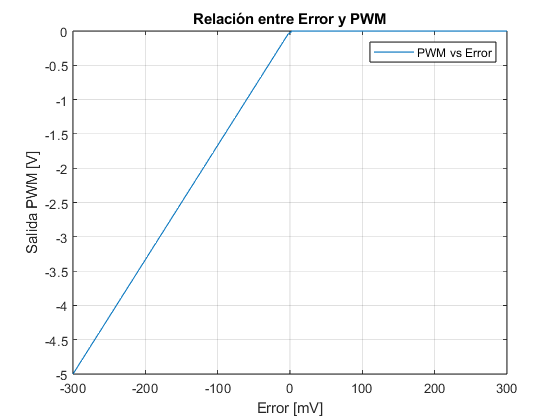


% Crear el modelo de función de transferencia
% Supongamos entrada U(s) (error) y salida Y(s) (PWM)
% Relación directa en dominio del tiempo: PWM = m * error + b
numerator = [m]; % Numerador (ganancia m)
denominator = [1]; % Denominador (sistema de primer orden, estático)
sys = tf(numerator, denominator);

% Visualizar la respuesta del sistema
% Definir un rango de errores desde -300 mV a +300 mV
error = linspace(-0.3, 0.3, 100); % [V]
PWM = m * error + b;

% Forzar PWM a ser cero para errores positivos
PWM(error > 0) = 0;

% Graficar
figure;
plot(error * 1000, PWM);
grid on;
xlabel('Error [mV]');
ylabel('Salida PWM [V]');
title('Relación entre Error y PWM');
legend('PWM vs Error');